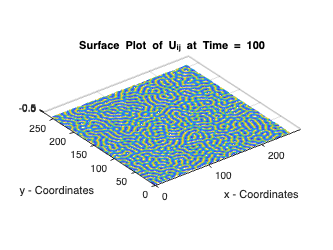

Number_of_Grid_Points = 256;

U0 = 1e-3 * (2 * rand(Number_of_Grid_Points, Number_of_Grid_Points) - 1); 
V0 = 1e-3 * (2 * rand(Number_of_Grid_Points, Number_of_Grid_Points) - 1); 
y0 = [reshape(U0, Number_of_Grid_Points^2, 1); reshape(V0, Number_of_Grid_Points^2, 1)];

[T, Y] = ode23(@(t, y) Q3a_FitzHugh_Nagumo_System(t, y), [0, 100], y0);

U_sol = reshape(Y(size(Y,1), 1:Number_of_Grid_Points^2), Number_of_Grid_Points, Number_of_Grid_Points);
V_sol = reshape(Y(size(Y,1), Number_of_Grid_Points^2+ 1:2*(Number_of_Grid_Points^2)), Number_of_Grid_Points, Number_of_Grid_Points);

U_Plot = surf(U_sol);
set(U_Plot, 'LineStyle', 'none');
daspect([1, 1, 1]);
xlabel('x - Coordinates');
xlim([0,275])
ylabel('y - Coordinates');
ylim([0,275])
title('Surface Plot of U_{ij} at Time = 100')

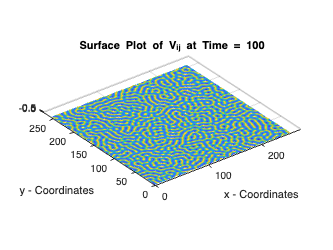


V_Plot = surf(V_sol);
set(V_Plot, 'LineStyle', 'none');
daspect([1, 1, 1]);
xlabel('x - Coordinates');
xlim([0,275])
ylabel('y - Coordinates');
ylim([0,275])
title('Surface Plot of V_{ij} at Time = 100')


%------------------------------------------------------------------------------------------------------------

%CODE IMPLEMENTED FOR DATA COLLECTION (PARTS B & C)

%{
[T1, Y1] = ode23(@(t, y) Q3a_FitzHugh_Nagumo_System_1(t, y), [0, 100], y0);

U_sol_1 = reshape(Y1(size(Y1,1), 1:Number_of_Grid_Points^2), Number_of_Grid_Points, Number_of_Grid_Points);

U_sol_1_Plot = surf(U_sol_1);
set(U_sol_1_Plot, 'LineStyle', 'none');
daspect([1, 1, 1]);
xlabel('x - Coordinates');
xlim([0,275])
ylabel('y - Coordinates');
ylim([0,275])
title('Surface Plot of U_{ij} at Time = 100');
saveas(gcf, 'Q3b.png');

[T2, Y2] = ode23(@(t, y) Q3a_FitzHugh_Nagumo_System_2(t, y), [0, 500], Y1(length(T1),:));

U_sol_2 = reshape(Y2(size(Y2,1), 1:Number_of_Grid_Points^2), Number_of_Grid_Points, Number_of_Grid_Points);

U_sol_2_Plot = surf(U_sol_2);
set(U_sol_2_Plot, 'LineStyle', 'none');
daspect([1, 1, 1]);
xlabel('x - Coordinates');
xlim([0,275])
ylabel('y - Coordinates');
ylim([0,275])
title('Surface Plot of U_{ij} at Time = 500');
saveas(gcf, 'Q3c.png');

function dy_dt = Q3a_FitzHugh_Nagumo_System_1(t, y)
   
    Constants = [0.45, 1, 0, 0.9, 1];

    Number_of_Grid_Points=256;
    Grid_Spacing = 1;
    
    U_Matrix = reshape(y(1:Number_of_Grid_Points^2), Number_of_Grid_Points, Number_of_Grid_Points);    
    V_Matrix = reshape(y(Number_of_Grid_Points^2+1:end), Number_of_Grid_Points, Number_of_Grid_Points);
    
    du_dt = Constants(1) * Laplacian(U_Matrix, Grid_Spacing) + U_Matrix - (U_Matrix.^3)/3 - V_Matrix;
    dv_dt = Constants(2) * Laplacian(V_Matrix, Grid_Spacing) + (U_Matrix - Constants(3) - Constants(4)*V_Matrix) / Constants(5);

    dy_dt = [reshape(du_dt, [Number_of_Grid_Points^2, 1]); reshape(dv_dt, [Number_of_Grid_Points^2, 1])];
end

function dy_dt = Q3a_FitzHugh_Nagumo_System_2(t, y)
   
    Constants = [0.45, 1, 0, 0.6, 1];

    Number_of_Grid_Points=256;
    Grid_Spacing = 1;
    
    U_Matrix = reshape(y(1:Number_of_Grid_Points^2), Number_of_Grid_Points, Number_of_Grid_Points);    
    V_Matrix = reshape(y(Number_of_Grid_Points^2+1:end), Number_of_Grid_Points, Number_of_Grid_Points);
    
    du_dt = Constants(1) * Laplacian(U_Matrix, Grid_Spacing) + U_Matrix - (U_Matrix.^3)/3 - V_Matrix;
    dv_dt = Constants(2) * Laplacian(V_Matrix, Grid_Spacing) + (U_Matrix - Constants(3) - Constants(4)*V_Matrix) / Constants(5);

    dy_dt = [reshape(du_dt, [Number_of_Grid_Points^2, 1]); reshape(dv_dt, [Number_of_Grid_Points^2, 1])];
end

%}

function dy_dt = Q3a_FitzHugh_Nagumo_System(t, y)
   
    Constants = [0.45, 1, 0, 0.9, 1];

    Number_of_Grid_Points = 256;
    Grid_Spacing = 1;
    
    U_Matrix = reshape(y(1:Number_of_Grid_Points^2), Number_of_Grid_Points, Number_of_Grid_Points);    
    V_Matrix = reshape(y(Number_of_Grid_Points^2+1:end), Number_of_Grid_Points, Number_of_Grid_Points);
    
    du_dt = Constants(1) * Laplacian(U_Matrix, Grid_Spacing) + U_Matrix - (U_Matrix.^3)/3 - V_Matrix;
    dv_dt = Constants(2) * Laplacian(V_Matrix, Grid_Spacing) + (U_Matrix - Constants(3) - Constants(4)*V_Matrix) / Constants(5);

    dy_dt = [reshape(du_dt, [Number_of_Grid_Points^2, 1]); reshape(dv_dt, [Number_of_Grid_Points^2, 1])];
end

function B=Laplacian(A,h)

tmp1=circshift(A,[1 1])+circshift(A,[-1 1])+circshift(A,[1 -1])+circshift(A,[-1 -1]);
tmp2=circshift(A,[0 1])+circshift(A,[0 -1])+circshift(A,[1 0])+circshift(A,[-1 0]);
B=(tmp1+4*tmp2-20*A)/(6*h^2);

end
